clear
clc
close all

Iappset_B64_fi = [0.5,0.75,1.0,1.25,1.5,2.0,2.5,3.0,3.5,4.0];
Iappset_B4_fi = [0.2,0.6,1.0,1.25,1.5,2.0,2.5,3.0,3.5,4.0,4.5,5.0];
Iappset_B34_fi = [0.5,1.0,1.5,2.0,2.5,3.0,3.25,3.5,4.0,4.5];
Iappset_B52_fi = [0.1,1,2,3,4,5,7,9];
Iappset_animal_B64_fi = [0.6,0.8,1.0,1.0,1.1,1.5,2.0];
Iappset_animal_B4_fi = [0.2,0.4,1.5,1.5,2,3.4,4.8];
Iappset_animal_B52_fi = [0.1,1,3,5];
% Iappset_animal_B52 = [0.1,1,3,5,8,9];
activationset_SNS_B64 = 0 * Iappset_B64_fi;
activationset_Costa_B64 = 0 * Iappset_B64_fi;
activationset_SNS_B4 = 0 * Iappset_B4_fi;
activationset_Costa_B4 = 0 * Iappset_B4_fi;
activationset_SNS_B34 = 0 * Iappset_B34_fi;
activationset_Costa_B34 = 0 * Iappset_B34_fi;
activationset_SNS_B52 = 0 * Iappset_B52_fi;
activationset_Costa_B52 = 0 * Iappset_B52_fi;
activationset_animal_B64 = [0,0,0,5.6763,17.3457,19.319,21] / 21;
activationset_animal_B4 = [0,0,0,3.33,6.67,13.33,30] / 30;
activationset_animal_B52 = [2,10,18,25] / 30;
% activationset_animal_B52 = [2,10,18,25,32,35]/38;

Iappset_B64 = [0.5,0.75,1.0,1.25,1.5,2.0,2.5,3.0,3.5,4.0];
tspan_B64 = [25,40];
col = length(Iappset_B64) / 2;
fmax_B64 = 12;
fmax_B64_fi = 12;
text_position_B64 = [8*0.95,0.9];

Iappset_B4 = [0.5,0.75,1.0,1.25,1.5,2.0,2.5,3.0,3.5,4.0];
tspan_B4 = [29,31];
% fmax = 15;
fmax_B4 = 15;
fmax_B4_fi = 15;
text_position_B4 = [8/15*2*0.95,0.9];

Iappset_B34 = [0.5,1.0,1.5,2.0,2.5,3.0,3.25,3.5,4.0,4.5];
tspan_B34 = [25,65];
fmax_B34 = 10;
fmax_B34_fi = 10;
% text_position_B34 = [8,0.9];
text_position_B34 = [21.5,0.9];

Iappset_B52 = [-5,-4,-3,-2,-1,1,2,3,4,5];
tspan_B52 = [25,65];
fmax_B52 = 15;
fmax_B52_fi = 15;
text_position_B52 = [21.5,0.9];

fontsize = 8;
tickwidth = 1;
linewidth = 2;

width_abs = 17.4;
height_abs = width_abs/2*(sqrt(5) - 1);

activation_height = 0.25 / 2;
input_height_ratio = 0.3;
delta_height_l_ratio = 0.2;
delta_height_s_ratio = 0.05;
axis_height_ratio = 0.05 / 2;

% activation_width = 0.15 / 2 / 1.2;
activation_width = 0.15 / 1.2;
input_width = activation_width;
delta_width_ratio = 0.1;
axis_width_ratio = axis_height_ratio*activation_height*height_abs/(width_abs*activation_width);
delta_width_fi_ratio = 0.5;
del_height_subfigure_ratio = 1;
del_width_subfigure_ratio = 1;
fi_width_ratio = 1.2;

left = 0.08;
bottom = 0.05;

legend_left = 0.3;
legend_height = 0.875;

text_position = [0,0.8];

tspan = [tspan_B64;tspan_B4;tspan_B34;tspan_B52];
fignum = {'(\bfA\rm) Model Comparison for B64','(\bfB\rm) Model Comparison for B4','(\bfA\rm) Model Comparison for B34','(\bfB\rm) Model Comparison for B52'};

neu_act_B64 = cell(length(Iappset_B64),1);
simout_Costa_B64 = cell(length(Iappset_B64),1);
for i = 1:length(Iappset_B64)
    Iapp = Iappset_B64(i);
    CtrlParaSNSTuning;
    simout_SNS_B64 = sim("B64SNSTest.slx");
    neu_act_B64{i} = simout_SNS_B64.f_B64;
    B64;
    simout_Costa_B64{i} = sim("B64CostaTest.slx");
end

neu_act_B4 = cell(length(Iappset_B4),1);
simout_Costa_B4 = cell(length(Iappset_B4),1);
for i = 1:length(Iappset_B4)
    Iapp = Iappset_B4(i);
    CtrlParaSNSTuning;
    simout_SNS_B4 = sim("B4SNSTest.slx");
    neu_act_B4{i} = simout_SNS_B4.f_B4;
    B4;
    simout_Costa_B4{i} = sim("B4CostaTest.slx");
end

neu_act_B34 = cell(length(Iappset_B34),1);
simout_Costa_B34 = cell(length(Iappset_B34),1);
for i = 1:length(Iappset_B34)
    Iapp = Iappset_B34(i);
    CtrlParaSNSTuning;
    simout_SNS_B34 = sim("B34SNSTest.slx");
    neu_act_B34{i} = simout_SNS_B34.f_B34;
    B34;
    simout_Costa_B34{i} = sim("B34CostaTest.slx");
end

neu_act_B52 = cell(length(Iappset_B52),1);
simout_Costa_B52 = cell(length(Iappset_B52),1);
for i = 1:length(Iappset_B52)
    Iapp = Iappset_B52(i);
    CtrlParaSNSTuning;
    simout_SNS_B52 = sim("B52SNSTest.slx");
    neu_act_B52{i} = simout_SNS_B52.f_B52;
    B52;
    simout_Costa_B52{i} = sim("B52CostaTest.slx");
end

for i = 1:length(Iappset_B64_fi)
    CtrlParaSNSTuning;
    Iapp = Iappset_B64_fi(i);
    simout_SNS_B64_fi = sim("B64SNSTest.slx");
    tstart = 30;
    timeindex = simout_SNS_B64_fi.f_B64(:,1) > tstart;
    activationset_SNS_B64(i) = max(simout_SNS_B64_fi.f_B64(timeindex,2));
    B64;
    simout_Costa_B64_fi = sim("B64CostaTest.slx");
    activationset_Costa_B64(i) = Costa_activation(simout_Costa_B64_fi.V_B64a,fmax_B64_fi);
end

for i = 1:length(Iappset_B4_fi)
    CtrlParaSNSTuning;
    Iapp = Iappset_B4_fi(i);
    simout_SNS_B4_fi = sim("B4SNSTest.slx");
    tstart = 30;
    timeindex = simout_SNS_B4_fi.f_B4(:,1) > tstart;
    activationset_SNS_B4(i) = max(simout_SNS_B4_fi.f_B4(timeindex,2));    
    B4;
    simout_Costa_B4_fi = sim("B4CostaTest.slx");
    activationset_Costa_B4(i) = Costa_activation(simout_Costa_B4_fi.V_B4,fmax_B4_fi);
end

for i = 1:length(Iappset_B34_fi)
    CtrlParaSNSTuning;
    Iapp = Iappset_B34_fi(i);
    simout_SNS_B34_fi = sim("B34SNSTest.slx");
    tstart = 10;
    timeindex = simout_SNS_B34_fi.f_B34(:,1) > tstart;
    activationset_SNS_B34(i) = max(simout_SNS_B34_fi.f_B34(timeindex,2));
    B34;
    simout_Costa_B34_fi = sim("B34CostaTest.slx");
    activationset_Costa_B34(i) = Costa_activation(simout_Costa_B34_fi.V_B34,fmax_B34_fi);
end

for i = 1:length(Iappset_B52_fi)
    CtrlParaSNSTuning;
    Iapp = Iappset_B52_fi(i);
    simout_SNS_B52_fi = sim("B52SNSTest.slx");
    tstart = 35;
    timeindex = simout_SNS_B52_fi.f_B52(:,1) > tstart;
    activationset_SNS_B52(i) = max(simout_SNS_B52_fi.f_B52(timeindex,2));
    B52;
    simout_Costa_B52_fi = sim("B52CostaTest.slx");
    activationset_Costa_B52(i) = Costa_activation(simout_Costa_B52_fi.V_B52,fmax_B52);
end

ylim_input = [0,5;0,5;0,5;-5,5];
ytick_input = [0,2.5,5;0,2.5,5;0,2.5,5;-5,0,5];
x_grid_width = [5,0.5,10,10];
ratio = 1.2/1.5;

figure
% set(gcf,'Units','centimeters')
set(gcf,'Position',[0,0,840*0.78,800*1.05])
ax = cell(5 * 2,(col + 3) * 1);
R_ave_B64 = 0;
R_ave_B4 = 0;
R_ave_B34 = 0;
R_ave_B52 = 0;
subfig_row = 1;
subfig_col = 1;
for i = 1:length(Iappset_B64)
    xtick = 0:5:15;
    ax = SNS_plot(ax,neu_act_B64{i},i,col,tspan_B64,linewidth,subfig_row,subfig_col,xtick);
    hold on
    [newtime_B64,fr_B64] = Costa_plot(simout_Costa_B64{i}.V_B64a,tspan_B64,fmax_B64,linewidth);
    R_B64 = R_plot(neu_act_B64{i},newtime_B64,fr_B64,tspan_B64,fontsize,text_position_B64);
    hold off
    R_ave_B64 = R_ave_B64 + R_B64;
    ax = input_plot(ax,simout_Costa_B64{i},i,col,tspan_B64,linewidth,subfig_row,subfig_col,ylim_input(1,:),xtick);
end

subfig_row = 2;
subfig_col = 1;
for i = 1:length(Iappset_B4)
    xtick = 0:1:2;
    ax = SNS_plot(ax,neu_act_B4{i},i,col,tspan_B4,linewidth,subfig_row,subfig_col,xtick);
    hold on
    [newtime_B4,fr_B4] = Costa_plot_B4(simout_Costa_B4{i}.V_B4,tspan_B4,fmax_B4,linewidth);
    R_B4 = R_plot_B4(neu_act_B4{i},newtime_B4,fr_B4,tspan_B4,fontsize,text_position_B4);
    hold off
    if i < 2 || i > 4
        R_ave_B4 = R_ave_B4 + R_B4;
    end
    ax = input_plot(ax,simout_Costa_B4{i},i,col,tspan_B4,linewidth,subfig_row,subfig_col,ylim_input(2,:),xtick);
end


ax = fi_plot(ax,Iappset_B64_fi,activationset_SNS_B64,activationset_Costa_B64,Iappset_animal_B64_fi,activationset_animal_B64,col,linewidth,1,1,fontsize);
ax = fi_plot(ax,Iappset_B4_fi,activationset_SNS_B4,activationset_Costa_B4,Iappset_animal_B4_fi,activationset_animal_B4,col,linewidth,2,1,fontsize);

ax = axis_plot(ax,col,tspan(1:2,:),tickwidth,fontsize,ylim_input,ytick_input,x_grid_width(1:2),ratio);
ax = arrange_plot(ax,col,left,bottom,activation_height,input_height_ratio,delta_height_l_ratio,delta_height_s_ratio,axis_height_ratio,activation_width,input_width,axis_width_ratio,delta_width_ratio,delta_width_fi_ratio,del_height_subfigure_ratio,del_width_subfigure_ratio,fi_width_ratio);
ax = grid_plot(ax,col);
ax = legend_plot(ax,col,fontsize,left,bottom,activation_width,activation_height,axis_width_ratio,axis_height_ratio,delta_width_ratio,delta_width_fi_ratio,fi_width_ratio,del_width_subfigure_ratio,delta_height_s_ratio,delta_height_l_ratio,del_height_subfigure_ratio,input_height_ratio);

leg_position =     0.7903    0.7754    0.1771    0.0524


leg_position =     0.7903    0.2813    0.1771    0.0524


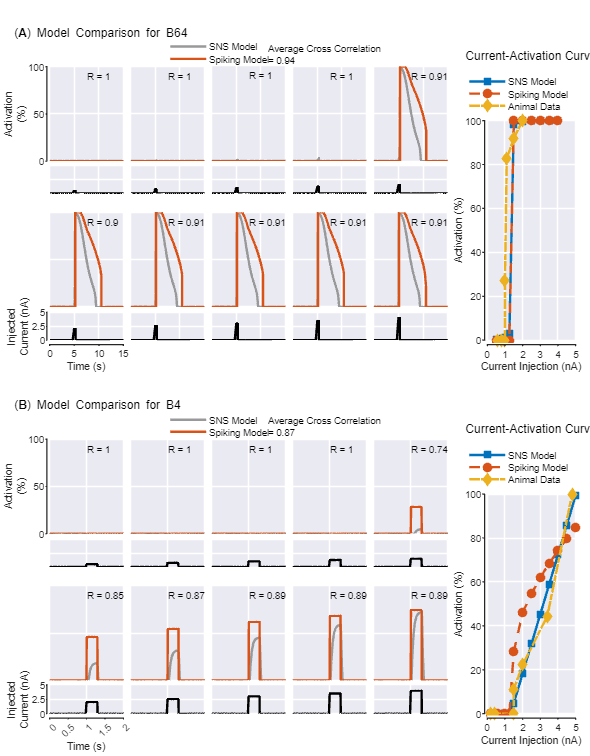

R_ave = [R_ave_B64 / 10,R_ave_B4 / 7];
for subfig_row = 1:2
    for subfig_col = 1:1
        i = subfig_row;
        set(gcf,"CurrentAxes",ax{1 + (subfig_row - 1) * 5,5 + (subfig_col - 1) * (col + 3)})
        text(-1/3 * (tspan(i,2) - tspan(i,1)),1.135,{'Average Cross Correlation',strjoin(["=",num2str(R_ave(subfig_row),2)])},'Fontsize',fontsize);

        set(gcf,"CurrentAxes",ax{1 + (subfig_row - 1) * 5,2 + (subfig_col - 1) * (col + 3)})
        text(-3/6 * (tspan(i,2) - tspan(i,1)),1.35,fignum{i},'Fontsize',10);

        set(gcf,"CurrentAxes",ax{1 + (subfig_row - 1) * 5,subfig_col * (col + 3)})
        text(5/2,1.3,"Current-Activation Curve",'Fontsize',10,'HorizontalAlignment','center');
    end
end

ylim_input = [0,5;0,5;0,5;-5,5];
ytick_input = [0,2.5,5;0,2.5,5;0,2.5,5;-5,0,5];
x_grid_width = [5,0.5,10,10];
ratio = 1.2/1.5;

figure
% set(gcf,'Units','centimeters')
set(gcf,'Position',[0,0,800*1.075,800*1.075])
ax = cell(5 * 2,(col + 3) * 1);
R_ave_B64 = 0;
R_ave_B4 = 0;
R_ave_B34 = 0;
R_ave_B52 = 0;

subfig_row = 1;
subfig_col = 1;
for i = 1:length(Iappset_B34)
    xtick = 0:10:40;
    ax = SNS_plot(ax,neu_act_B34{i},i,col,tspan_B34,linewidth,subfig_row,subfig_col,xtick);
    hold on
    [newtime_B34,fr_B34] = Costa_plot(simout_Costa_B34{i}.V_B34,tspan_B34,fmax_B34,linewidth);
    R_B34 = R_plot_B34(neu_act_B34{i},newtime_B34,fr_B34,tspan_B34,fontsize,text_position_B34);
    hold off
    R_ave_B34 = R_ave_B34 + R_B34;
    ax = input_plot(ax,simout_Costa_B34{i},i,col,tspan_B34,linewidth,subfig_row,subfig_col,ylim_input(3,:),xtick);
end

subfig_row = 2;
subfig_col = 1;
for i = 1:length(Iappset_B52)
    xtick = 0:10:40;
    ax = SNS_plot(ax,neu_act_B52{i},i,col,tspan_B52,linewidth,subfig_row,subfig_col,xtick);
    hold on
    [newtime_B52,fr_B52] = Costa_plot(simout_Costa_B52{i}.V_B52,tspan_B52,fmax_B52,linewidth);
    R_B52 = R_plot_B52(neu_act_B52{i},newtime_B52,fr_B52,tspan_B52,fontsize,text_position_B52);
    hold off
    if i < 5 || i > 5
        R_ave_B52 = R_ave_B52 + R_B52;
    end
    ax = input_plot(ax,simout_Costa_B52{i},i,col,tspan_B52,linewidth,subfig_row,subfig_col,ylim_input(4,:),xtick);
    
end

ax = fi_plot(ax,Iappset_B34_fi,activationset_SNS_B34,activationset_Costa_B34,[],[],col,linewidth,1,1,fontsize);
ax = fi_plot(ax,Iappset_B52_fi,activationset_SNS_B52,activationset_Costa_B52,Iappset_animal_B52_fi,activationset_animal_B52,col,linewidth,2,1,fontsize);

ax = axis_plot(ax,col,tspan(3:4,:),tickwidth,fontsize,ylim_input,ytick_input,x_grid_width(3:4),ratio);
ax = arrange_plot(ax,col,left,bottom,activation_height,input_height_ratio,delta_height_l_ratio,delta_height_s_ratio,axis_height_ratio,activation_width,input_width,axis_width_ratio,delta_width_ratio,delta_width_fi_ratio,del_height_subfigure_ratio,del_width_subfigure_ratio,fi_width_ratio);
ax = grid_plot(ax,col);
ax = legend_plot_2(ax,col,fontsize,left,bottom,activation_width,activation_height,axis_width_ratio,axis_height_ratio,delta_width_ratio,delta_width_fi_ratio,fi_width_ratio,del_width_subfigure_ratio,delta_height_s_ratio,delta_height_l_ratio,del_height_subfigure_ratio,input_height_ratio);

leg_position =     0.8331    0.7917    0.1349    0.0355


leg_position =     0.8331    0.2829    0.1349    0.0512


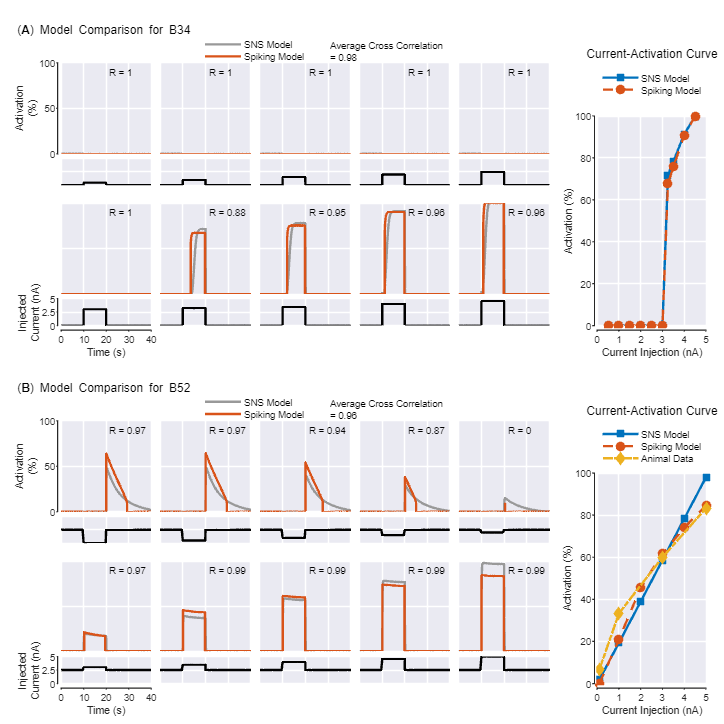

i = 3

i = 4

R_ave = [R_ave_B34 / 10,R_ave_B52 / 9];
for subfig_row = 1:2
    for subfig_col = 1:1
        i = subfig_row + 2
        set(gcf,"CurrentAxes",ax{1 + (subfig_row - 1) * 5,5 + (subfig_col - 1) * (col + 3)})
        text(-1/3 * (tspan(i,2) - tspan(i,1)),1.135,{'Average Cross Correlation',strjoin(["=",num2str(R_ave(subfig_row),2)])},'Fontsize',fontsize);

        set(gcf,"CurrentAxes",ax{1 + (subfig_row - 1) * 5,2 + (subfig_col - 1) * (col + 3)})
        text(-3/6 * (tspan(i,2) - tspan(i,1)),1.35,fignum{i},'Fontsize',10);

        set(gcf,"CurrentAxes",ax{1 + (subfig_row - 1) * 5,subfig_col * (col + 3)})
        text(5/2,1.3,"Current-Activation Curve",'Fontsize',10,'HorizontalAlignment','center');
    end
end

function ax = SNS_plot(ax,neu_act,i,col,tspan,linewidth,subfig_row,subfig_col,xtick)
    rownum = (subfig_row - 1) * 5 + 2 * floor((i - 1) / col) + 1;
    colnum = (subfig_col - 1) * (col + 3) + mod(i - 1,col) + 2;
    ax{rownum,colnum} = subplot(5 * 2,col + 3,(rownum - 1) * (col + 3) + colnum);
    plot(neu_act(:,1) - tspan(1),neu_act(:,2),'LineWidth',linewidth,'Color',[0.6,0.6,0.6])
    xlim(tspan - tspan(1))
    set(gca,'XTick',xtick)
    ylim([0,1])
    set(gca,'box','off','XColor','none','YColor','none')
    set(gca,'YTick',0:0.5:1)
end

function ax = fi_plot(ax,Iappset_fi,activationset_SNS,activationset_Cost,Iappset_animal_fi,activationset_animal,col,linewidth,subfig_row,subfig_col,fontisze)
    rownum = (subfig_row - 1) * 5 + 1:(subfig_row - 1) * 5 + 4;
    colnum = (subfig_col - 1) * (col + 3) + 8;
    ax{rownum(1),colnum} = subplot(5 * 2,col + 3,(rownum - 1) * (col + 3) + colnum);
    plot(Iappset_fi,activationset_SNS,'-s','MarkerFaceColor',[0, 0.4470, 0.7410],'MarkerEdgeColor',[0, 0.4470, 0.7410],'LineWidth',linewidth,'Color',[0 0.4470 0.7410]);
    hold on
    plot(Iappset_fi,activationset_Cost,'--o','Color',[0.8500, 0.3250, 0.0980],'MarkerFaceColor',[0.8500, 0.3250, 0.0980],'MarkerEdgeColor',[0.8500, 0.3250, 0.0980],'LineWidth',linewidth);
    if ~isempty(Iappset_animal_fi)
        plot(Iappset_animal_fi,activationset_animal,'-.diamond','Color',[0.9290 0.6940 0.1250],'MarkerFaceColor',[0.9290 0.6940 0.1250],'MarkerEdgeColor',[0.9290 0.6940 0.1250],'LineWidth',linewidth);
    end
    xlim([0,5])
    set(gca,'XTick',0:1:5)
    ylim([0,1])
    set(gca,'YTick',0:0.2:1)
    set(gca,'box','off','XColor','none','YColor','none')
    hold off
end

function [newtime,fr] = Costa_plot(V,tspan,fmax,linewidth)
    timeindex = find((V(2:end,2) > 0).*(V(1:end - 1,2) < 0) > 0.5);
    is_spike = size(timeindex);
    if is_spike(1) == 0
        newtime = V(:,1);
        fr = zeros(size(newtime));
    else
        fr = zeros(size(timeindex) - [1 0]);
        for k = 1:length(timeindex) - 1
            fr(k) = 1/(V(timeindex(k + 1),1) - V(timeindex(k),1));
        end
        timeindex(end) = [];
        newtime = V(1:timeindex(1) - 1,1);
        newtime = [newtime; V(timeindex,1)];
        newtime = [newtime; V(timeindex(end) + 1:end,1)];
        fr = [zeros(size(V(1:timeindex(1)-1,1))); fr; zeros(size(V(timeindex(end) + 1:end,1)))];
    end
    fr = min(fr./fmax,1);

    plot(newtime - tspan(1),fr,'LineWidth',linewidth,'Color',[0.8500, 0.3250, 0.0980])
end

function [newtime,newfr] = Costa_plot_B4(V,tspan,fmax,linewidth)
    timeindex = find((V(2:end,2) > 0).*(V(1:end - 1,2) < 0) > 0.5);
    is_spike = size(timeindex);
    newtime = V(:,1);
    newfr = zeros(size(newtime));
    if is_spike(1) > 1
        fr = 1/(V(timeindex(1 + 1),1) - V(timeindex(1),1));
        newfr((V(:,1) < 30 + 0.3).*(V(:,1) > 30) > 0.5) = fr;
    end
    newfr = min(newfr./fmax,1);

    plot(newtime - tspan(1),newfr,'LineWidth',linewidth,'Color',[0.8500, 0.3250, 0.0980])
end

function R = R_plot(neu_act,newtime,fr,tspan,fontsize,text_position)
    SNS_time_index = (neu_act(:,1) >= tspan(1) - 1).*(neu_act(:,1) <= tspan(2) + 1) > 0.5;
    activation_SNS = interp1(neu_act(SNS_time_index,1),neu_act(SNS_time_index,2),linspace(tspan(1),tspan(2),1000*(tspan(2)-tspan(1))));
    Costa_time_index = (newtime >= tspan(1)-0.2).*(newtime <= tspan(2)+0.2) > 0.5;
    activation_Costa = interp1(newtime(Costa_time_index),fr(Costa_time_index),linspace(tspan(1),tspan(2),1000*(tspan(2)-tspan(1))));
    if max(abs(activation_SNS)) < 0.1 && max(abs(activation_Costa)) < 0.1
        R = 1;
    elseif max(abs(activation_SNS)) < 0.1 || max(abs(activation_Costa)) < 0.1
        R = 0;
    else
        R = (activation_SNS*activation_Costa')/sqrt(sum(activation_SNS.^2)*sum(activation_Costa.^2));
    end
    text(text_position(1),text_position(2),['R = ' num2str(R,2)],'Fontsize',fontsize);
end

function R = R_plot_B4(neu_act,newtime,fr,tspan,fontsize,text_position)
    SNS_time_index = (neu_act(:,1) >= tspan(1) - 1).*(neu_act(:,1) <= tspan(2) + 1) > 0.5;
    activation_SNS = interp1(neu_act(SNS_time_index,1),neu_act(SNS_time_index,2),linspace(tspan(1),tspan(2),1000*(tspan(2)-tspan(1))));
    Costa_time_index = (newtime >= tspan(1)-0.2).*(newtime <= tspan(2)+0.2) > 0.5;
    activation_Costa = interp1(newtime(Costa_time_index),fr(Costa_time_index),linspace(tspan(1),tspan(2),1000*(tspan(2)-tspan(1))));
    if max(abs(activation_SNS)) < 0.02 && max(abs(activation_Costa)) < 0.02
        R = 1;
    elseif max(abs(activation_SNS)) < 0.02 || max(abs(activation_Costa)) < 0.02
        R = 0;
    else
        R = (activation_SNS*activation_Costa')/sqrt(sum(activation_SNS.^2)*sum(activation_Costa.^2));
    end
    text(text_position(1),text_position(2),['R = ' num2str(R,2)],'Fontsize',fontsize);
end

function R = R_plot_B34(neu_act,newtime,fr,tspan,fontsize,text_position)
    SNS_time_index = (neu_act(:,1) >= tspan(1) - 1).*(neu_act(:,1) <= tspan(2) + 1) > 0.5;
    activation_SNS = interp1(neu_act(SNS_time_index,1),neu_act(SNS_time_index,2),linspace(tspan(1),tspan(2),1000*(tspan(2)-tspan(1))));
    Costa_time_index = (newtime >= tspan(1)-0.2).*(newtime <= tspan(2)+0.2) > 0.5;
    activation_Costa = interp1(newtime(Costa_time_index),fr(Costa_time_index),linspace(tspan(1),tspan(2),1000*(tspan(2)-tspan(1))));
    if max(abs(activation_SNS)) < 0.1 && max(abs(activation_Costa)) < 0.1
        R = 1;
    elseif max(abs(activation_SNS)) < 0.1 || max(abs(activation_Costa)) < 0.1
        R = 0;
    else
        R = (activation_SNS*activation_Costa')/sqrt(sum(activation_SNS.^2)*sum(activation_Costa.^2));
    end
    text(text_position(1),text_position(2),['R = ' num2str(R,2)],'Fontsize',fontsize);
end

function R = R_plot_B52(neu_act,newtime,fr,tspan,fontsize,text_position)
    SNS_time_index = (neu_act(:,1) >= tspan(1) - 2).*(neu_act(:,1) <= tspan(2) + 2) > 0.5;
    activation_SNS = interp1(neu_act(SNS_time_index,1),neu_act(SNS_time_index,2),linspace(tspan(1),tspan(2),1000*(tspan(2)-tspan(1))));
    Costa_time_index = (newtime >= tspan(1) - 2).*(newtime <= tspan(2) + 2) > 0.5;
    activation_Costa = interp1(newtime(Costa_time_index),fr(Costa_time_index),linspace(tspan(1),tspan(2),1000*(tspan(2)-tspan(1))));
    if max(abs(activation_SNS)) < 0.05 && max(abs(activation_Costa)) < 0.05
        R = 1;
    elseif max(abs(activation_SNS)) < 0.1 || max(abs(activation_Costa)) < 0.1
        R = 0;
    else
        R = (activation_SNS*activation_Costa')/sqrt(sum(activation_SNS.^2)*sum(activation_Costa.^2));
    end
    text(text_position(1),text_position(2),['R = ' num2str(R,2)],'Fontsize',fontsize);
end


function ax = input_plot(ax,simout,i,col,tspan,linewidth,subfig_row,subfig_col,ylim_input,xtick)
    rownum = (subfig_row - 1) * 5 + 2 * floor((i - 1) / col) + 1 + 1;
    colnum = (subfig_col - 1) * (col + 3) + mod(i - 1,col) + 2;
    ax{rownum,colnum} = subplot(5 * 2,col + 3,(rownum - 1) * (col + 3) + colnum);
    plot(simout.Iapp(:,1) - tspan(1),simout.Iapp(:,2),'LineWidth',linewidth,'Color','k')
    xlim(tspan - tspan(1))
    set(gca,'XTick',xtick)
    ylim(ylim_input)
    set(gca,'box','off','XColor','none',...
        'YColor','none')
    set(gca,'YTick',linspace(ylim_input(1),ylim_input(2),3))
end

function ax = axis_plot(ax,col,tspan,tickwidth,fontsize,ylim_input,ytick_input,x_grid_width,ratio)
for subfig_row = 1:2
    for subfig_col = 1:1
        ax{1 + (subfig_row - 1) * 5,(subfig_col - 1) * (col + 3) + 1} = subplot(2 * 5,col + 3,1 + (col + 3) * (subfig_row - 1) * 5 + (subfig_col - 1) * (col + 3));
        ylim([0,1])
        ylabel({'Activation','(%)'})
        set(gca,'box','off','XColor','none',...
            'ytick',[0,0.5,1],'yticklabel',{'0','50','100'},...
            'TickDir','out','LineWidth',tickwidth,...
            'TickLength',[0.01,0.01]*ratio,...
            'FontSize',fontsize,'FontName', 'Arial')

        ax{4 + (subfig_row - 1) * 5,(subfig_col - 1) * (col + 3) + 1} = subplot(2 * 5,col + 3,1 + (col + 3) * (3 + (subfig_row - 1) * 5) + (subfig_col - 1) * (col + 3));
        ylim(ylim_input(2 * (subfig_row - 1) + subfig_col,:))
        ylabel({'Injected','Current (nA)'})
        set(gca,'box','off','XColor','none',...
            'ytick',ytick_input(2 * (subfig_row - 1) + subfig_col,:),'yticklabel',string(ytick_input(2 * (subfig_row - 1) + subfig_col,:)),...
            'TickDir','out','LineWidth',tickwidth,...
            'TickLength',[0.01,0.01]*ratio,...
            'FontSize',fontsize,'FontName', 'Arial')

        ax{subfig_row * 5, (subfig_col - 1) * (col + 3) + 2} = subplot(2 * 5,col + 3,2 + (col + 3) * (subfig_row * 5 - 1) + (subfig_col - 1) * (col + 3));
        tspan_neu = tspan(subfig_row,:);
        xlim(tspan_neu - tspan_neu(1))
        xlabel('Time (s)')
        set(gca,'box','off','YColor','none',...
            'xtick',0:x_grid_width(subfig_row):tspan_neu(2)-tspan_neu(1),'yticklabel',string(0:5:tspan_neu(2)-tspan_neu(1)),...
            'TickDir','out','LineWidth',tickwidth,...
            'TickLength',[0.01,0.01],...
            'FontSize',fontsize,'FontName', 'Arial')


        ax{1 + (subfig_row - 1) * 5,(subfig_col - 1) * (col + 3) + col + 2} = subplot(2 * 5,col + 3,col + 2 + (col + 3) * (subfig_row - 1) * 5 + (subfig_col - 1) * (col + 3):col + 3:col + 2 + (col + 3) * ((subfig_row - 1) * 5 + 3) + (subfig_col - 1) * (col + 3));
        ylim([0,1])
        ylabel('Activation (%)')
        set(gca,'box','off','XColor','none',...
            'ytick',0:0.2:1,'yticklabel',string(0:20:100),...
            'TickDir','out','LineWidth',tickwidth,...
            'TickLength',[0.01,0.01]*ratio,...
            'FontSize',fontsize,'FontName', 'Arial')

        ax{subfig_row * 5, subfig_col * (col + 3)} = subplot(2 * 5,col + 3,col + 3 + (col + 3) * (subfig_row * 5 - 1) + (subfig_col - 1) * (col + 3));
        xlim([0,5])
        xlabel('Current Injection (nA)')
        set(gca,'box','off','YColor','none',...
            'xtick',0:1:5,'xticklabel',string(0:1:5),...
            'TickDir','out','LineWidth',tickwidth,...
            'TickLength',[0.01,0.01],...
            'FontSize',fontsize,'FontName', 'Arial')
    end
end
end

function maxact = Costa_activation(V,fmax)
    timeindex = find((V(2:end,2) > 0).*(V(1:end - 1,2) < 0) > 0.5);
    is_spike = size(timeindex);
    if is_spike(1) < 2
        newtime = V(:,1);
        fr = zeros(size(newtime));
    else
        fr = zeros(size(timeindex) - [1 0]);
        for k = 1:length(timeindex) - 1
            fr(k) = 1/(V(timeindex(k + 1),1) - V(timeindex(k),1));
        end
        timeindex(end) = [];
        newtime = V(1:timeindex(1) - 1,1);
        newtime = [newtime; V(timeindex,1)];
        newtime = [newtime; V(timeindex(end) + 1:end,1)];
        fr = [zeros(size(V(1:timeindex(1)-1,1))); fr; zeros(size(V(timeindex(end) + 1:end,1)))];
    end
    fr = min(fr./fmax,1);
    maxact = max(fr);
end

function ax = arrange_plot(ax,col,left,bottom,activation_height,input_height_ratio,delta_height_l_ratio,delta_height_s_ratio,axis_height_ratio,activation_width,input_width,axis_width_ratio,delta_width_ratio,delta_width_fi_ratio,del_height_subfigure_ratio,del_width_subfigure_ratio,fi_width_ratio)
    input_height = input_height_ratio*activation_height;
    delta_height_l = delta_height_l_ratio*activation_height;
    delta_height_s = delta_height_s_ratio*activation_height;
    axis_height = axis_height_ratio*activation_height;
    axis_width = axis_width_ratio*activation_width;
    delta_width = delta_width_ratio*activation_width;
    delta_width_fi = delta_width_fi_ratio*activation_width;
    del_height_subfigure = del_height_subfigure_ratio*activation_height;
    del_width_subfigure = del_width_subfigure_ratio*activation_width;
    fi_width = fi_width_ratio*activation_width;

    for subfig_row = 1:2
        for subfig_col = 1:1
            left_subfigure = left + (2*axis_width + (4 * delta_width + 5 * activation_width) + delta_width_fi + 2*axis_width + fi_width + del_width_subfigure) * (subfig_col - 1);
            bottom_subfigure = bottom + (2*axis_height + (2 * delta_height_s + 2 * input_height + delta_height_l + 2 * activation_height) + del_height_subfigure) * (2 - subfig_row);
            for i = 1:col + 1
                for j = 2:2:4 + 1
                    positionij = get(ax{j + (subfig_row - 1) * 5,i + (subfig_col - 1) * (col + 3)},'position');
                    positionij(1) = left_subfigure + 2*axis_width + (i - 2)*(delta_width + activation_width);
                    positionij(2) = bottom_subfigure + 2*axis_height + (4 - j) / 2 * (delta_height_s + input_height + delta_height_l + activation_height);
                    positionij(3) = input_width;
                    positionij(4) = input_height;
                    set(ax{j + (subfig_row - 1) * 5,i + (subfig_col - 1) * (col + 3)},'position',positionij);
                end
                for j = 1:2:4 + 1
                    positionij = get(ax{j + (subfig_row - 1) * 5,i + (subfig_col - 1) * (col + 3)},'position');
                    positionij(1) = left_subfigure + 2*axis_width + (i - 2)*(delta_width + activation_width);
                    positionij(2) = bottom_subfigure + 2*axis_height + input_height + delta_height_s + (3 - j)/2*(activation_height + delta_height_l + input_height + delta_height_s);
                    positionij(3) = activation_width;
                    positionij(4) = activation_height;
                    set(ax{j + (subfig_row - 1) * 5,i + (subfig_col - 1) * (col + 3)},'position',positionij);
                end
            end
            i = 1;
            for j = 1:5
                positionij =  get(ax{j + (subfig_row - 1) * 5,i + (subfig_col - 1) * (col + 3)},'position');
                positionij(1) = left_subfigure;
                positionij(3) = axis_width;
                set(ax{j + (subfig_row - 1) * 5,i + (subfig_col - 1) * (col + 3)},'position',positionij);
            end
            j = 5;
            for i = 1:col + 1
                positionij = get(ax{j + (subfig_row - 1) * 5,i + (subfig_col - 1) * (col + 3)},'position');
                positionij(2) = bottom_subfigure;
                positionij(4) = axis_height;
                set(ax{j + (subfig_row - 1) * 5,i + (subfig_col - 1) * (col + 3)},'position',positionij);
            end

            j = 1;
            i = col + 3;
            left_fi = left_subfigure + 2*axis_width + (4 * delta_width + 5 * activation_width) + delta_width_fi;
            positionij =  get(ax{j + (subfig_row - 1) * 5,i + (subfig_col - 1) * (col + 3)},'position');
            positionij(1) = left_fi + 2*axis_width;
            positionij(2) = bottom_subfigure + 2*axis_height;
            positionij(3) = fi_width;
            positionij(4) = (2 * activation_height + delta_height_l + 2 * input_height + 2 * delta_height_s) * 0.8;
            set(ax{j + (subfig_row - 1) * 5,i + (subfig_col - 1) * (col + 3)},'position',positionij);

            j = 1;
            i = col + 2;
            positionij =  get(ax{j + (subfig_row - 1) * 5,i + (subfig_col - 1) * (col + 3)},'position');
            positionij(1) = left_fi;
            positionij(2) = bottom_subfigure + 2*axis_height;
            positionij(3) = axis_width;
            positionij(4) = (2 * activation_height + delta_height_l + 2 * input_height + 2 * delta_height_s) * 0.8;
            set(ax{j + (subfig_row - 1) * 5,i + (subfig_col - 1) * (col + 3)},'position',positionij);

            j = 5;
            i = col + 3;
            positionij =  get(ax{j + (subfig_row - 1) * 5,i + (subfig_col - 1) * (col + 3)},'position');
            positionij(1) = left_fi + 2*axis_width;
            positionij(2) = bottom_subfigure;
            positionij(3) = fi_width;
            positionij(4) = axis_height;
            set(ax{j + (subfig_row - 1) * 5,i + (subfig_col - 1) * (col + 3)},'position',positionij);

        end
    end

end

function ax = grid_plot(ax,col)
    for subfig_row = 1:2
        for subfig_col = 1:1
            for i = 2:col + 1
                for j = 2:4 + 1
                    set(ax{6 - j + (subfig_row - 1) * 5,i + (subfig_col - 1) * (col + 3)},'XGrid','on','YGrid','on',...
                        'Color',[234,234,242]/255,...
                        'GridColor',[1,1,1],'GridAlpha',1)
                end
            end
            j = 5;
            i = col + 3;
            set(ax{6 - j + (subfig_row - 1) * 5,i + (subfig_col - 1) * (col + 3)},'XGrid','on','YGrid','on',...
                'Color',[234,234,242]/255,...
                'GridColor',[1,1,1],'GridAlpha',1)
        end
    end
end

function ax = legend_plot(ax,col,fontsize,left,bottom,activation_width,activation_height,axis_width_ratio,axis_height_ratio,delta_width_ratio,delta_width_fi_ratio,fi_width_ratio,del_width_subfigure_ratio,delta_height_s_ratio,delta_height_l_ratio,del_height_subfigure_ratio,input_height_ratio)
    input_height = input_height_ratio*activation_height;    
    axis_width = axis_width_ratio*activation_width;
    axis_height = axis_height_ratio*activation_height;
    delta_width = delta_width_ratio*activation_width;
    delta_width_fi = delta_width_fi_ratio*activation_width;
    fi_width = fi_width_ratio*activation_width;
    del_width_subfigure = del_width_subfigure_ratio*activation_width;
    del_height_subfigure = del_height_subfigure_ratio*activation_height;
    delta_height_s = delta_height_s_ratio*activation_height;
    delta_height_l = delta_height_l_ratio*activation_height;
    for subfig_row = 1:2
        for subfig_col = 1:1
            set(gcf,"CurrentAxes",ax{(subfig_row - 1) * 5 + 1,(subfig_col - 1) * (col + 3) + ceil(col/2) + 1})
            leg = legend('SNS Model','Spiking Model',...
                'FontSize',fontsize,'Location','northoutside');
            rect = leg.Position;
            left_subfigure = left + (2*axis_width + (4 * delta_width + 5 * activation_width) + delta_width_fi + 2*axis_width + fi_width + del_width_subfigure) * (subfig_col - 1);
            bottom_subfigure = bottom + (2*axis_height + (2 * delta_height_s + 2 * input_height + delta_height_l + 2 * activation_height) + del_height_subfigure) * (2 - subfig_row);

            rect(1) = left_subfigure + 2*axis_width + delta_width + 1.5 * activation_width;
            rect(2) = bottom_subfigure + 2*axis_height + 2 * delta_height_s + 2 * input_height + delta_height_l + 2 * activation_height + 0 * axis_height;
            set(leg,'Position',rect)
            legend boxoff
        
            set(gcf,"CurrentAxes",ax{(subfig_row - 1) * 5 + 1,subfig_col * (col + 3)})
            % if subfig_row == 1 && subfig_col == 1
            %     location = "northoutside";
            % else
            %     location = "northoutside";
            % end
            
            h = legend('SNS Model','Spiking Model','Animal Data',...
                    'FontSize',fontsize,'Location','north');
            legend boxoff
            leg_position = h.Position
            leg_position(2) = leg_position(2) + 0.075;
            h.Position = leg_position;
            

        end
    end
end

function ax = legend_plot_2(ax,col,fontsize,left,bottom,activation_width,activation_height,axis_width_ratio,axis_height_ratio,delta_width_ratio,delta_width_fi_ratio,fi_width_ratio,del_width_subfigure_ratio,delta_height_s_ratio,delta_height_l_ratio,del_height_subfigure_ratio,input_height_ratio)
    input_height = input_height_ratio*activation_height;    
    axis_width = axis_width_ratio*activation_width;
    axis_height = axis_height_ratio*activation_height;
    delta_width = delta_width_ratio*activation_width;
    delta_width_fi = delta_width_fi_ratio*activation_width;
    fi_width = fi_width_ratio*activation_width;
    del_width_subfigure = del_width_subfigure_ratio*activation_width;
    del_height_subfigure = del_height_subfigure_ratio*activation_height;
    delta_height_s = delta_height_s_ratio*activation_height;
    delta_height_l = delta_height_l_ratio*activation_height;
    for subfig_row = 1:2
        for subfig_col = 1:1
            set(gcf,"CurrentAxes",ax{(subfig_row - 1) * 5 + 1,(subfig_col - 1) * (col + 3) + ceil(col/2) + 1})
            leg = legend('SNS Model','Spiking Model',...
                'FontSize',fontsize,'Location','northoutside');
            rect = leg.Position;
            left_subfigure = left + (2*axis_width + (4 * delta_width + 5 * activation_width) + delta_width_fi + 2*axis_width + fi_width + del_width_subfigure) * (subfig_col - 1);
            bottom_subfigure = bottom + (2*axis_height + (2 * delta_height_s + 2 * input_height + delta_height_l + 2 * activation_height) + del_height_subfigure) * (2 - subfig_row);

            rect(1) = left_subfigure + 2*axis_width + delta_width + 1.5 * activation_width;
            rect(2) = bottom_subfigure + 2*axis_height + 2 * delta_height_s + 2 * input_height + delta_height_l + 2 * activation_height + 0 * axis_height;
            set(leg,'Position',rect)
            legend boxoff
        
            set(gcf,"CurrentAxes",ax{(subfig_row - 1) * 5 + 1,subfig_col * (col + 3)})
            % if subfig_row == 1 && subfig_col == 1
            %     location = "northoutside";
            % else
            %     location = "northoutside";
            % end
            
            if subfig_row == 1 && subfig_col == 1
                h = legend('SNS Model','Spiking Model',...
                    'FontSize',fontsize,'Location','north');
            else
                h = legend('SNS Model','Spiking Model','Animal Data',...
                    'FontSize',fontsize,'Location','north');
            end
            legend boxoff
            leg_position = h.Position
            leg_position(2) = leg_position(2) + 0.075;
            h.Position = leg_position;
            

        end
    end
end